# Racing Line Optimizer

### Import track data

track = readmatrix("my_track.csv")

track =          0         0    0.0500    0.0500
    0.0458   -0.0122    0.0500    0.0500
    0.0918   -0.0240    0.0500    0.0500
    0.1378   -0.0354    0.0500    0.0500
    0.1838   -0.0464    0.0500    0.0500
    0.2300   -0.0570    0.0500    0.0500
    0.2762   -0.0672    0.0500    0.0500
    0.3225   -0.0771    0.0500    0.0500
    0.3689   -0.0865    0.0500    0.0500
    0.4153   -0.0956    0.0500    0.0500


### Define variables

trackName = 'Silverstone';
m = 75; % Mass of vehicle
ftmax = 1.6; % Max acceleration (m/s^2)
fbmax = 1.8; % Min acceleration (m/s^2)
fnmax = 3.0; % Max cornering acceleration (m/s^2)

### Generate optimized path

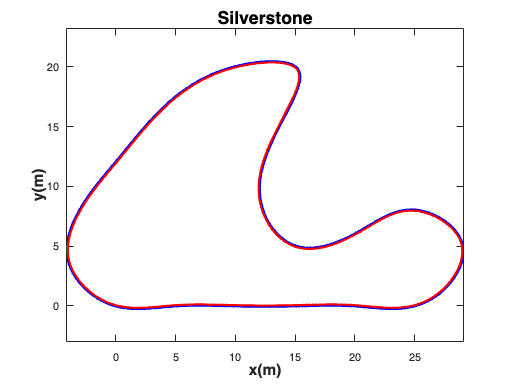


 Iter            Fval  Primal Infeas    Dual Infeas  Complementarity  
    0   -7.612261e-05   0.000000e+00   1.454750e-04     1.000000e+00  
    1   -4.132019e-05   0.000000e+00   7.273749e-08     2.502501e-01  
    2   -4.164333e-05   0.000000e+00   3.636873e-11     2.847311e-04  
    3   -5.030105e-05   0.000000e+00   3.098961e-13     9.601214e-06  
    4   -1.089723e-04   5.551115e-17   4.848169e-15     1.160385e-06  
    5   -1.476554e-04   1.443290e-15   5.237250e-16     1.652687e-07  
    6   -1.576694e-04   5.091413e-16   1.093925e-16     3.189768e-08  
    7   -1.599533e-04   1.426810e-16   3.073943e-17     8.558909e-09  

Minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the 

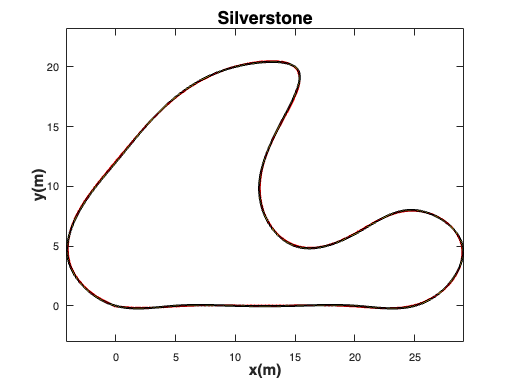

[trajMCP, trackData] = minCurvaturePathGenFunction(track,trackName);

% Click on the drop down menu to select the method for generating the optimized path

### Generate velocity profile

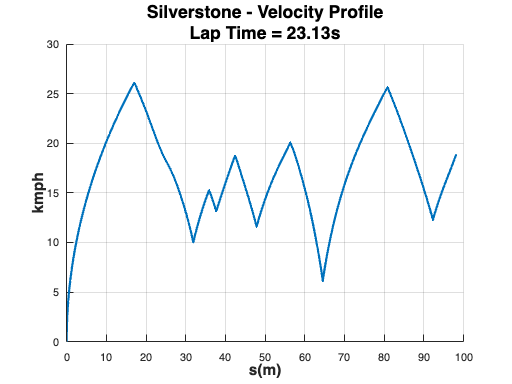

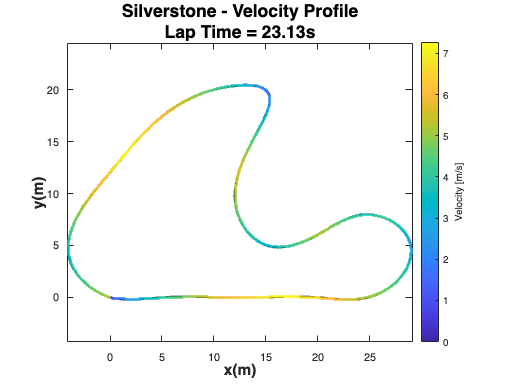

[velProf,len] = velProfCalcFunction(trajMCP,trackName,m,ftmax,fbmax,fnmax,trackData);

### References:

- The Silverstone racetrack data has been ta    ken from the following GitHub repository: [https://github.com/TUMFTM/racetrack-database](https://github.com/TUMFTM/racetrack-database) 

- The function, "velProfCalcFunction" uses the function, "curvature" that has been taken from the following File Exchange: [https://www.mathworks.com/matlabcentral/fileexchange/69452-curvature-of-a-1d-curve-in-a-2d-or-3d-space](https://www.mathworks.com/matlabcentral/fileexchange/69452-curvature-of-a-1d-curve-in-a-2d-or-3d-space) 